k_e = 0.3824

k_e = 0.3824

k_m = 0.3824

k_m = 0.3824

J = 0.0019

J = 0.0019

R = 4.6296

R = 4.6296


t = 0.0:0.01:0.5;
y_ir = (k_m / (R * J)) * exp(- (k_e * k_m) / (R * J) * t)

y_ir =    43.4731   36.8149   31.1764   26.4015   22.3579   18.9336   16.0337   13.5780   11.4985    9.7374    8.2460    6.9831    5.9136    5.0079    4.2409    3.5913    3.0413    2.5755    2.1810    1.8470    1.5641    1.3246    1.1217    0.9499    0.8044    0.6812    0.5769    0.4885    0.4137    0.3503    0.2967    0.2512    0.2128    0.1802    0.1526    0.1292    0.1094    0.0927    0.0785    0.0665    0.0563    0.0477    0.0404    0.0342    0.0289    0.0245    0.0208    0.0176    0.0149    0.0126


y_sr = (1 / k_e) * (1 - exp(- (k_e * k_m) / (R * J) * t))

y_sr =          0    0.4005    0.7397    1.0269    1.2702    1.4761    1.6506    1.7983    1.9234    2.0293    2.1190    2.1950    2.2593    2.3138    2.3600    2.3990    2.4321    2.4601    2.4839    2.5040    2.5210    2.5354    2.5476    2.5579    2.5667    2.5741    2.5804    2.5857    2.5902    2.5940    2.5972    2.5999    2.6023    2.6042    2.6059    2.6073    2.6085    2.6095    2.6103    2.6111    2.6117    2.6122    2.6126    2.6130    2.6133    2.6136    2.6138    2.6140    2.6142    2.6143



y_c = sign(t + 0.1) / k_e

y_c =     2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151


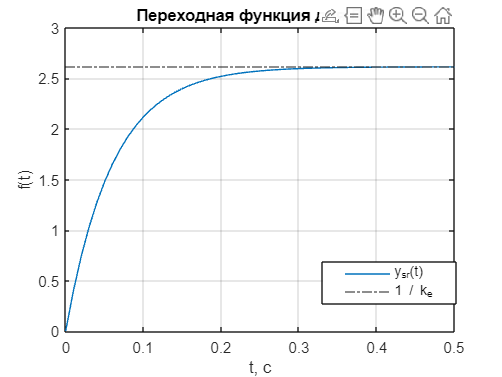


%w = 0.0:0.01:0.5
%A = k_m / sqrt ((k_m * k_e) ^ 2 + (J * R * w) ^ 2)
%phi = atan(- (w * R * J) / (k_e * k_m))

%plot(t, y_ir, 'DisplayName', 'y_{ir}(t)')

plot(t, y_sr)


yline(1 / k_e, '-.')

grid()
%title('Весовая функция для ДПТ')
title('Переходная функция для ДПТ')
legend('y_{sr}(t)', '1 / k_e', "Position", [0.67,0.21473,0.21205,0.070685])
ylabel('f(t)')
xlabel('t, с')